## **Phase-Amplitude Coupling Analysis**

The PAC method used here is the same as described in Canolty et al, (2010).

The first section of this demo shows how to set up the simulated data and run the PAC routine. The second section will break down the key elements of the PAC routine. The final section will demonstrate the data output and baseline vs surrogate methods for the control of spurious coupling.

## **1) Setting up the Demo**

We will simulate a signal with the following properties

- 100 epochs

- 2000 ms epoch length

- 6 hz carrier signal

- 40 hz modulated signal

- baseline period runs for the first 900ms

load('cfc_data.mat');

amps = 18:60;
phases = 4:12;
surrs = 100;
entrainmentfreq = 40;
samprate = 1000;
baseline = 1:900;
eventperiod = 901:2000;
vertextouse = 1;

% EEGLAG TOOLBOX IS REQUIRED TO RUN THE FILTERING ROUTINES
% DOWNLOAD LINK: https://sccn.ucsd.edu/eeglab/download.php
% Please activate EEGFILT to continue

[output] = meg_cfc_pipeline_demo(cfc_data,vertextouse,amps,phases,eventperiod,baseline,samprate,entrainmentfreq,surrs);

## **2) PAC routine**

First we need to define the measurement windows, sampling rate, modulated frequency of interest, and the number of surrogates. In this example we are only going to use a single channel.

% Setup the primary variables
wind = 901:2000;
blwind = baseline;
sr = samprate;
entfrq = entrainmentfreq;
surrs = 100;

% get dimension sizes
[~,tp,trr] = size(cfc_data);

% set indices for cfc normalisation
ioi = false(tp,1);
ioi(wind) = true;
ioib = false(tp,1);
ioib(blwind) = true;

% create window to normalise time series amplitudes to
normwind = false(tp,1);
normwind(200:length(normwind)-200) = true; % exclude edges



After preparing the setup variables we filter the data and perform the hilbert transform to extract the instantaneous amplitude and phase values.

[ampdata,phasedata] = bpfilterDEMO(amps,phases,cfc_data,sr,tp,trr);
[Hamp,Hphase] = sigtransDEMO(ampdata,phasedata);
figure;plot(Hamp(23,:,1)); legend('40 Hz Amplitude');
figure;plot(Hphase(3,:,1));legend('6 Hz phase');


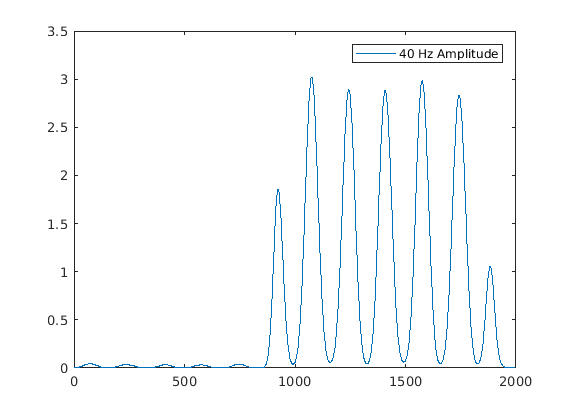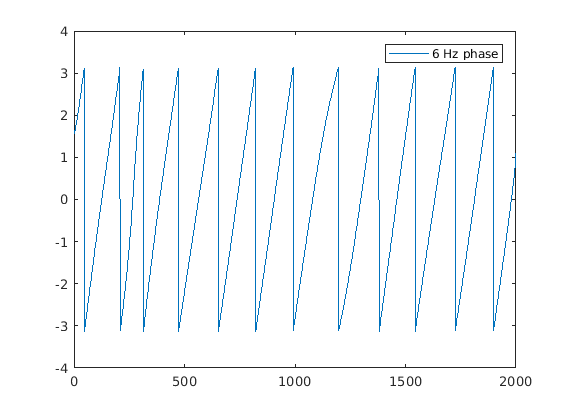

With the phase and amplitude information across our range of frequencies we can now run PAC

At this stage the function will also perform a routine to assess the ratio of sinusoidal to non-sinusoidal waveforms. This is described in detail in Seymour et al, (2017). 

% PAC is highlight sensitive to amplitude differences. 
% The data are scaled to normalise the amplitudes across trials.

% Stimulation period coupling
[Xs]=cfcDEMO(Hphase,Hamp,phases,sr,ioi,normwind);
% Baseline period coupling
[Xb]=cfcDEMO(Hphase,Hamp,phases,sr,ioib,normwind); 

% prepare surrogate cfc storage
Xss = zeros(numel(amps),numel(phases),surrs);
Xsb = zeros(numel(amps),numel(phases),surrs);
[~,surrtemplates] = randpermsurrDEMO(phasedata,surrs,trr,2,wind);
[~,surrtemplateb] = randpermsurrDEMO(phasedata,surrs,trr,2,blwind);
parfor ii = 1:surrs
    % routine described in Canolty et al, 2010
    [Xss(:,:,ii)]=cfcDEMO(surrtemplates(:,:,:,ii),Hamp,phases,sr,ioi,normwind);
    [Xsb(:,:,ii)]=cfcDEMO(surrtemplateb(:,:,:,ii),Hamp,phases,sr,ioib,normwind);
    disp(num2str(ii))
end
testS = Xss(23,3,:);
figure;histogram(testS);
title('Theta/Gamma PAC -- stim period')
xlabel('PAC value')
testB = Xss(23,3,:);
figure;histogram(testB);
title('Theta/Gamma PAC -- baseline period')
xlabel('PAC value')


**SURROGATE VALUES**

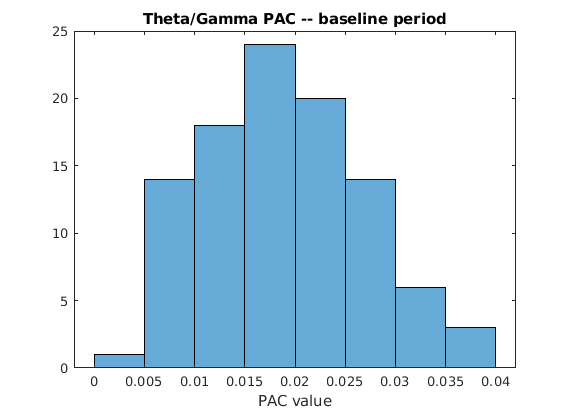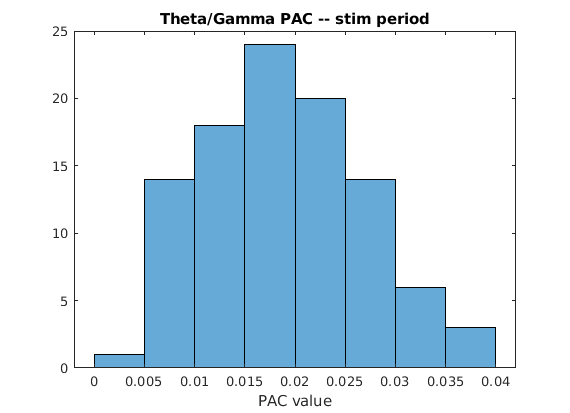

The final stage requires us to correct for spurious coupling. This can be done by subtracting active from baseline coupling, or z-transforming using the surrogate values. Both methods are theoretically sound and depend on the data being used. Surrogates are ideal when the data are continuous or the baseline is known to contain a signal that would represent a significant bias. Baseline correction is ideal when we want to correct against a cortically "idle" period to get an idea of task specific coupling, or rather a task related change in coupling. A third option is to correct both periods against their own surrogates and then look at task related changes, yet this can be problematic when we consider that the baseline is already relatively noisy activity but should still contain more semblance of coupling than a surrogate version of it. This can lead to an artificially inflated z-score that would then run the risk of being greater than that of the stimulation/task period. 


% Correct for Spurious Coupling

% BL Approach
Xd = Xs-Xb;

% Z-transform Approach
hdxss = zeros(1,surrs);
hdxsb = zeros(1,surrs);
% find indices to use
test=phases.*amps';
hypphase = 6;
hypamp = entfrq;
f = find(phases==hypphase);
ff = find(test(:,f)==hypphase*hypamp);
% z test val = matrix(ff,f);
for ii = 1:surrs
    hdxss(:,ii) = squeeze(Xss(ff,f,ii));
    hdxsb(:,ii) = squeeze(Xsb(ff,f,ii));
end
Zhypcfcs= (Xs-mean(hdxss))./std(hdxss);
Zhypcfcb = (Xb-mean(hdxsb))./std(hdxsb);

## **3) PAC Data**

Now that we have the data ready lets take a look at the PAC inherrent in our data. 

% Raw Stim CFC
figure;imagesc(phases,amps, Xs); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Raw Stim CFC')

% Raw Baseline CFC
figure;imagesc(phases,amps, Xb); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Raw Baseline CFC')

% Mean Surrogate CFC (stim)
figure;imagesc(phases,amps, mean(Xss,3)); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Surrogate Stim CFC')

% Mean Surrogate CFC (stim)
figure;imagesc(phases,amps, mean(Xsb,3)); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Surrogate Baseline CFC')

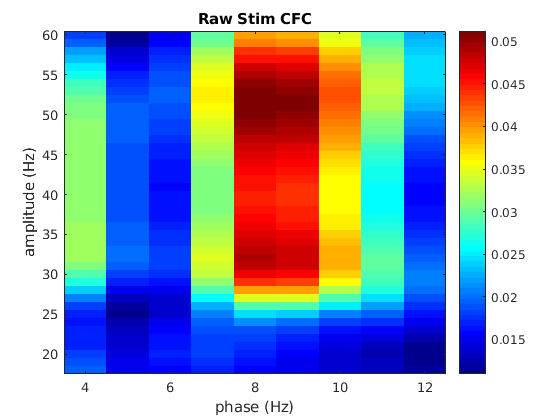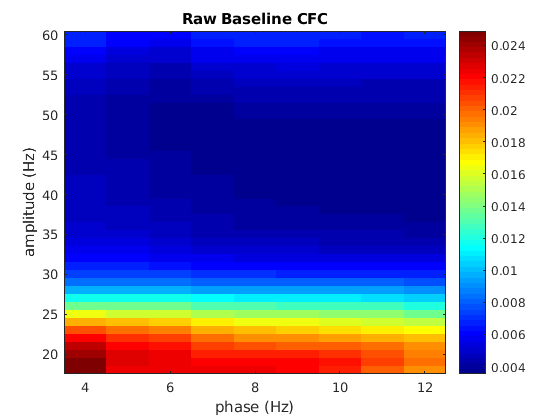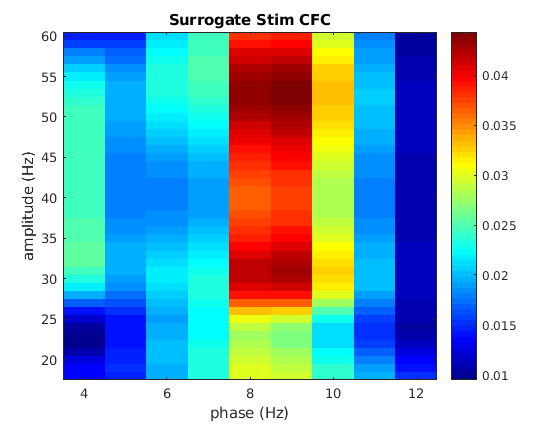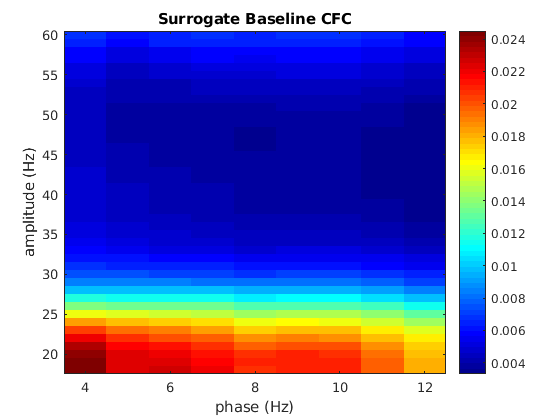

% baseline corrected PACfigure;imagesc(phases,amps, Xd); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('BLC Corrected Stim CFC')

% surrogate corrected PAC
figure;imagesc(phases,amps, Zhypcfcs); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Z Stim CFC')

% surrogate corrected PAC
figure;imagesc(phases,amps, Zhypcfcb); axis xy; colormap jet; colorbar;
xlabel('phase (Hz)'); ylabel('amplitude (Hz)');
title('Z BL CFC')